pfile = 'data_0011.p';
 cfg_result = extract_setupstr(pfile);
 %cfg_result = 'data_0004.cfg';
% %Convert to Physical Units
  %data = odas_p2mat(pfile,'vehicle','vmp','profile_dir','down');  %vmp downward profile
 %data = odas_p2mat(pfile,'constant_temp', 'T1_fast');  
data = odas_p2mat(pfile);

No bad records were found in file /Users/jotri/Documents/MATLAB/odas/data_0011.p

Address Matrix:
   0   0   1   2   5   7   8   9
  32  40   1   2   5   7   8   9
  41  42   1   2   5   7   8   9
   4   6   1   2   5   7   8   9
  10  11   1   2   5   7   8   9
  12  48   1   2   5   7   8   9
   0  49   1   2   5   7   8   9
   0  50   1   2   5   7   8   9

     channel:  0 = Gnd
     channel:  1 = Ax
     channel:  2 = Ay
     channel:  4 = T1
     channel:  5 = T1_dT1
     channel:  6 = T2
     channel:  7 = T2_dT2
     channel:  8 = sh1
     channel:  9 = sh2
     channel: 10 = P
     channel: 11 = P_dP
     channel: 12 = PV
     channel: 32 = V_Bat
     channel: 40 = Incl_Y
     channel: 41 = Incl_X
     channel: 42 = Incl_T
even channel: 48 = JAC_C
 odd channel: 49 = JAC_C
     channel: 50 = JAC_T


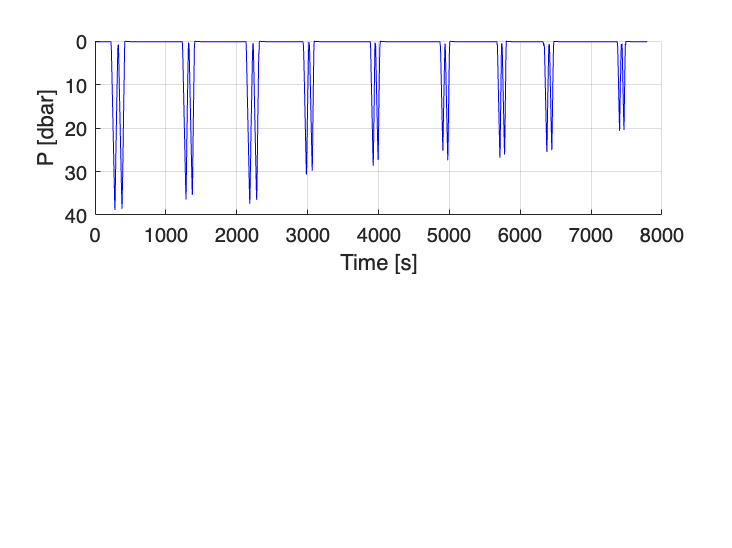


%-------------------PATCH, RUN ONCE---------------------
% Patch file to change to vmp and downward (only done for data_004.p so far)
% setup = extract_setupstr(pfile,'setup.cfg');   %extracts setup file named setup.cfg for editing (correct from rvmp (up) to vmp (down))
% 
%  cal_info = cal_FP07_in_situ;
%  cal_info.profile_min_W = 0.5; %per code provided - note different from profiles below
%  cal_info.order = 1; 
%  filename = [pfile(1:end-2) '.mat'];
%  diss = quick_look(pfile,[],[]); close all
%  for p=1:diss.profiles_in_this_file
%      [T0_1(p),b_T1(p),lags_T1(p)]=cal_FP07_in_situ(filename,'JAC_T','T1','T2655',...
%          cal_info,'profile_num',p,'make_figures',false)
%  end
%  T0_T1 = mean(T0_1);
%  beta_T1=mean(b_T1);
%  % -->  add to setup_corrected.cfg manually
% 

  patch_setupstr(pfile,'data_0011.cfg')
%-------------------------------------------------------

%TIMES ARE IN UTC ON INSTRUMENT - NEED TO CONVERT TO LOCAL TIME

%Pressure and Profile Identification
pMin = 1.5;   %Min pressure (dbar)
wMin = 0.6;   %Min dP/dt = vertical velocity if diff(P) since dt = 1 s (dbar/s)
minDuration = 10;   %Minimum duration (s)
% [P records] = show_P(pfile);     
% dP_dt = gradient(P_slow,1/fs_slow);

figure(100), subplot(2,1,1), hold on, plot(data.t_slow, data.P_slow,'b'), grid on; set(gca,'ydir','rev'), xlabel('Time [s]'), ylabel('P [dbar]')

ind_profile_slow = get_profile(data.P_slow, data.W_slow, pMin, wMin, 'down', minDuration, data.fs_slow);

%odas_p2mat('data_0011');
load('data_0011.mat');


%defining input variables
T = JAC_T;
P_cvt = convert_odas(P,'P',setupfilestr);
S = salinity(P_cvt,JAC_T,JAC_C);
P = 1.5:1:40 %pressure bins

P =     1.5000    2.5000    3.5000    4.5000    5.5000    6.5000    7.5000    8.5000    9.5000   10.5000   11.5000   12.5000   13.5000   14.5000   15.5000   16.5000   17.5000   18.5000   19.5000   20.5000   21.5000   22.5000   23.5000   24.5000   25.5000   26.5000   27.5000   28.5000   29.5000   30.5000   31.5000   32.5000   33.5000   34.5000   35.5000   36.5000   37.5000   38.5000   39.5000


line = 'C';

%Create arrays to use in tempcompmatrix and salinitiesmatrix

temperature_values_profiles = [];
pressure_values_profiles = [];
salinity_values_profiles = [];

% Initialize cell arrays to hold the profiles
temperature_values_profiles = cell(1, length(ind_profile_slow));
pressure_values_profiles = cell(1, length(ind_profile_slow));
salinity_values_profiles = cell(1, length(ind_profile_slow));

k = 1; % Initialize k to index profiles
for i = 1:length(ind_profile_slow)
    temperature_values = T(ind_profile_slow(1,i):ind_profile_slow(2,i));
    pressure_values = P_cvt(ind_profile_slow(1,i):ind_profile_slow(2,i));
    salinity_values = S(ind_profile_slow(1,i):ind_profile_slow(2,i));

    % Store the entire temperature and pressure profiles in cell arrays
    temperature_values_profiles{k} = temperature_values; 
    pressure_values_profiles{k} = pressure_values; 
    salinity_values_profiles{k} = salinity_values;
    
    k = k + 1;
end

## Create 1D Variable Matrices


%create temperature/salinity matrix for desired pressure bins. Function
%takes avg salinity/pressure for eaach bin (.5)

thetempcompmatrix = tempcompmatrix(pressure_values_profiles,temperature_values_profiles,setupfilestr, fs_fast,pMin, 1);

Dataset 1: Depth range in data: 1.92 to 37.95 dbar
Dataset 1: Depth: 1.500000e+00 dbar, Average Temperature: 13.07°C
Dataset 1: Depth: 2.500000e+00 dbar, Average Temperature: 13.05°C
Dataset 1: Depth: 3.500000e+00 dbar, Average Temperature: 12.88°C
Dataset 1: Depth: 4.500000e+00 dbar, Average Temperature: 11.86°C
Dataset 1: Depth: 5.500000e+00 dbar, Average Temperature: 11.40°C
Dataset 1: Depth: 6.500000e+00 dbar, Average Temperature: 11.10°C
Dataset 1: Depth: 7.500000e+00 dbar, Average Temperature: 10.84°C
Dataset 1: Depth: 8.500000e+00 dbar, Average Temperature: 10.64°C
Dataset 1: Depth: 9.500000e+00 dbar, Average Temperature: 10.55°C
Dataset 1: Depth: 1.050000e+01 dbar, Average Temperature: 10.49°C
Dataset 1: Depth: 1.150000e+01 dbar, Average Temperature: 10.43°C
Dataset 1: Depth: 1.250000e+01 dbar, Average Temperature: 10.37°C
Dataset 1: Depth: 1.350000e+01 dbar, Average Temperature: 10.29°C
Dataset 1: Depth: 1.450000e+01 dbar, Average Temperature: 10.26°C
Dataset 1: Depth: 1.55000

thesalinitymatrix = salinitiesmatrix(pressure_values_profiles,salinity_values_profiles,setupfilestr, fs_fast,pMin, 1);

Dataset 1: Depth range in data: 1.92 to 37.95 dbar
Dataset 1: Depth: 1.500000e+00 dbar, Average Salinity: 33.87
Dataset 1: Depth: 2.500000e+00 dbar, Average Salinity: 33.86
Dataset 1: Depth: 3.500000e+00 dbar, Average Salinity: 33.78
Dataset 1: Depth: 4.500000e+00 dbar, Average Salinity: 33.80
Dataset 1: Depth: 5.500000e+00 dbar, Average Salinity: 33.87
Dataset 1: Depth: 6.500000e+00 dbar, Average Salinity: 33.87
Dataset 1: Depth: 7.500000e+00 dbar, Average Salinity: 33.88
Dataset 1: Depth: 8.500000e+00 dbar, Average Salinity: 33.90
Dataset 1: Depth: 9.500000e+00 dbar, Average Salinity: 33.92
Dataset 1: Depth: 1.050000e+01 dbar, Average Salinity: 33.91
Dataset 1: Depth: 1.150000e+01 dbar, Average Salinity: 33.91
Dataset 1: Depth: 1.250000e+01 dbar, Average Salinity: 33.91
Dataset 1: Depth: 1.350000e+01 dbar, Average Salinity: 33.92
Dataset 1: Depth: 1.450000e+01 dbar, Average Salinity: 33.92
Dataset 1: Depth: 1.550000e+01 dbar, Average Salinity: 33.91
Dataset 1: Depth: 1.650000e+01 dba

temperature_matrix = thetempcompmatrix';
salinity_matrix = thesalinitymatrix';
% rho = density(salinity_matrix,temperature_matrix);
% rho_matrix = rho *1000

## GSW Variables


Prep = repmat(P',1,18);

SA = gsw_SA_from_SP(salinity_matrix,Prep,-120.7, 35.1);
CT = gsw_CT_from_t(SA,temperature_matrix,Prep);
rho_matrix = gsw_rho(SA,CT,Prep);
sigma_0_matrix = gsw_rho(SA,CT,0);
abs_salinity_matrix = SA;

Prep = repmat(P',1,18);
 %N = sqrt((9.81./rho_matrix(1:end-1,:)).*(diff(sigma_0_matrix)./diff(Prep)));
% Ntwo = (9.81./rho_matrix(1:end-1,:)).*(diff(sigma_0_matrix)./diff(Prep));
 %Prep =  Prep(1:38,:);

 % Apply central difference
dSigma_0 = (sigma_0_matrix(3:end, :) - sigma_0_matrix(1:end-2, :)) ./ (Prep(3:end, :) - Prep(1:end-2, :));
dRho = (rho_matrix(3:end, :) - rho_matrix(1:end-2, :)) ./ (Prep(3:end, :) - Prep(1:end-2, :));

% frequency calculation using central difference
N = sqrt((9.81 ./ rho_matrix(2:end-1, :)) .* (dSigma_0 ./ (Prep(3:end, :) - Prep(1:end-2, :))));

% N^2 
Ntwo = (9.81 ./ rho_matrix(2:end-1, :)) .* (dSigma_0 ./ (Prep(3:end, :) - Prep(1:end-2, :)));

% Prep matrix adjustment
Prep = Prep(1:end-2, :);

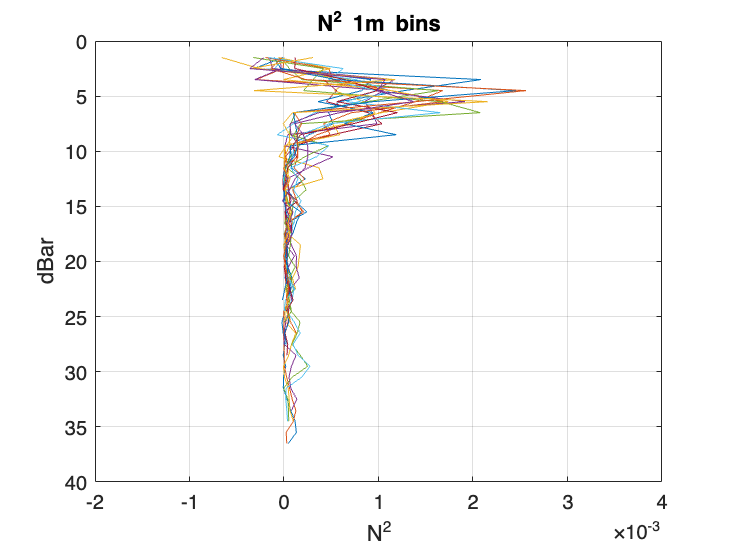

figure;
plot(Ntwo, Prep);
set(gca, 'YDir', 'reverse');  % Reverse the y-axis
grid on;
xlabel('N^2');
ylabel('dBar');
xlim([-2*10^-3, 4*10^-3]);  % Set x-axis limits
 % Set y-axis limits (adjust this range as needed)
title('N^2 1m bins');